# This is Q4 of the assignment.

Defining the signals

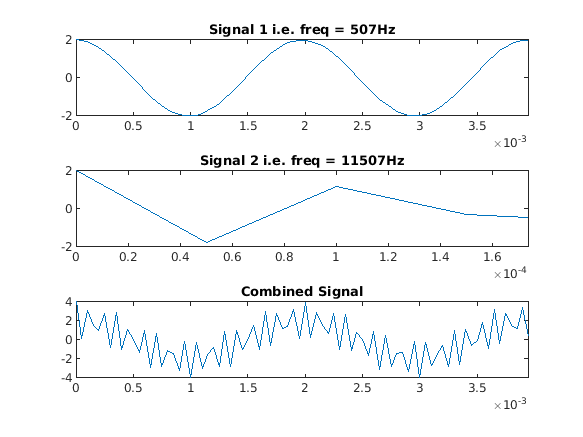

fsampling = 20000;

t = linspace(0,2,2*20000);
amp = 2;

freq_1 = 507;
freq_2 = 11507;

sig_1 = amp*cos(2*pi*freq_1*t);
sig_2 = amp*cos(2*pi*freq_2*t);
inp_sig = sig_1 + sig_2;

subplot(3,1,1),plot(t,sig_1);
title('Signal 1 i.e. freq = 507Hz'), axis([0 2/507 -2 2]);
subplot(3,1,2),plot(t,sig_2);
title('Signal 2 i.e. freq = 11507Hz'), axis([0 2/11507 -2 2]);
subplot(3,1,3),plot(t,inp_sig);
title('Combined Signal'), axis([0 2/507 -4 4]);

Now doing the fourier transform and creating the required Magnitude function of frequency.

y = fft(inp_sig);
len_y = length(y);
x = linspace(0,10000,len_y);

Plotting the magnitude spectrum.

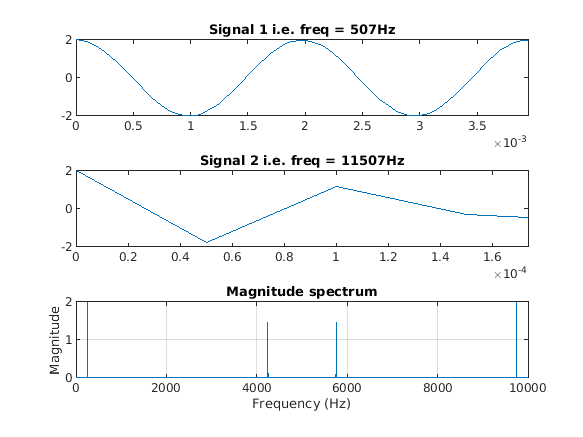

hold off
plot(x,abs(y/20000));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude spectrum');
grid;